# ME2801: HW3, Time Response.

This live script is meant to complement the Nise solutions for the MATLAB exercises for time response

## Nise 4.3

Step resonse for these two first-order systems

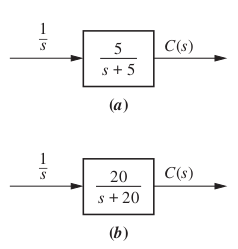

Enter each TF into MATAB

Ga = tf([5], [1 5])


Ga =
 
    5
  -----
  s + 5
 
Continuous-time transfer function.
Model Properties


Gb = tf(20, [1 20])


Gb =
 
    20
  ------
  s + 20
 
Continuous-time transfer function.
Model Properties


Plot the step responses.  Nise has them combined in one figure window, let's do them separately.

figure(1);
clf()
step(Ga)
figure(2);
clf();
step(Gb)

For the MATLAB plots, add annotation (by hand or using the computer) to indicate the time-constant of the system.

You can do this many ways - by hand with a pencil/pen, using MATLAB's GUI figure editting or programmatically like this...

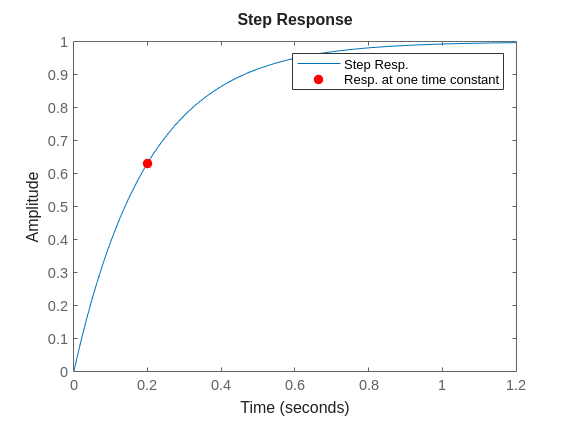

% Time constant
tau_a = 1/5;
% DC gain
K_a = 1.0;
figure(1);
hold on
plot(tau_a, K_a*(1-exp(-1)), 'ro', "MarkerFaceColor","r")
legend('Step Resp.','Resp. at one time constant')

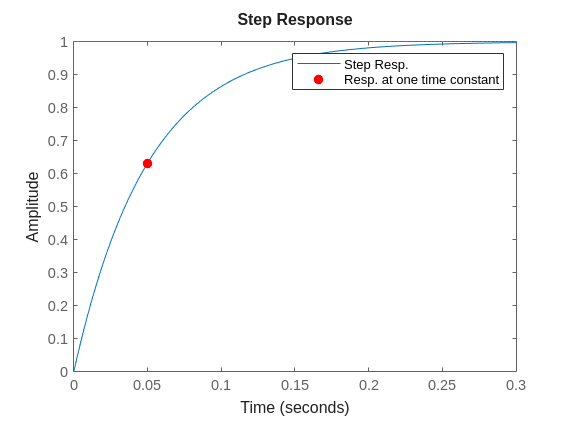


tau_b = 1/20;
K_b = 1.0;
figure(2);
hold on
plot(tau_b, K_b*(1-exp(-1)), 'ro', "MarkerFaceColor","r")
legend('Step Resp.','Resp. at one time constant')

Optionally check your hand caculations form 4.2

stepinfo(Ga)

ans = struct with fields:
         RiseTime: 0.4394
    TransientTime: 0.7824
     SettlingTime: 0.7824
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 1.4644


stepinfo(Gb)

ans = struct with fields:
         RiseTime: 0.1099
    TransientTime: 0.1956
     SettlingTime: 0.1956
      SettlingMin: 0.9045
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 0.3661


## 4.21

Using MATLAB to check the hand calculations

Ga = tf(16, [1 3 16])


Ga =
 
        16
  --------------
  s^2 + 3 s + 16
 
Continuous-time transfer function.
Model Properties


Gb = tf(0.04, [1 0.02 0.04])


Gb =
 
         0.04
  -------------------
  s^2 + 0.02 s + 0.04
 
Continuous-time transfer function.
Model Properties


Gc = tf(1.05e7, [1 1.6e3 1.05e7])


Gc =
 
         1.05e07
  ----------------------
  s^2 + 1600 s + 1.05e07
 
Continuous-time transfer function.
Model Properties


It is sufficient to just print the values like this...

stepinfo(Ga)

ans = struct with fields:
         RiseTime: 0.3569
    TransientTime: 2.6570
     SettlingTime: 2.6570
      SettlingMin: 0.9213
      SettlingMax: 1.2803
        Overshoot: 28.0255
       Undershoot: 0
             Peak: 1.2803
         PeakTime: 0.8596


damp(Ga)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.50e+00 + 3.71e+00i     3.75e-01       4.00e+00         6.67e-01    
 -1.50e+00 - 3.71e+00i     3.75e-01       4.00e+00         6.67e-01    



stepinfo(Gb)

ans = struct with fields:
         RiseTime: 5.4160
    TransientTime: 380.0163
     SettlingTime: 380.0163
      SettlingMin: 0.2699
      SettlingMax: 1.8545
        Overshoot: 85.4461
       Undershoot: 0
             Peak: 1.8545
         PeakTime: 15.7080


damp(Gb)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.00e-02 + 2.00e-01i     5.00e-02       2.00e-01         1.00e+02    
 -1.00e-02 - 2.00e-01i     5.00e-02       2.00e-01         1.00e+02    



stepinfo(Gc)

ans = struct with fields:
         RiseTime: 3.9036e-04
    TransientTime: 0.0044
     SettlingTime: 0.0044
      SettlingMin: 0.7985
      SettlingMax: 1.4480
        Overshoot: 44.8011
       Undershoot: 0
             Peak: 1.4480
         PeakTime: 9.7860e-04


damp(Gc)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -8.00e+02 + 3.14e+03i     2.47e-01       3.24e+03         1.25e-03    
 -8.00e+02 - 3.14e+03i     2.47e-01       3.24e+03         1.25e-03    
